# Tarea 1

# Control Robusto y Análisis  de Desempeño  : Vehículo Aéreo no Tripulado. 

## Dylan Ortiz Mayorga

## Juan Pablo Vallejo Montañez

### Universidad Nacional de Colombia 

#### **1.Consideraciónes Inciales**

clc 
clear
load("modelo_lin.mat");

El objetivo es diseñar controladores PID y Hinf para una planta correspondiente a una aeronave tipo UAV. Se parte de un modelo nominal  lineal acoplado.

Para cada uno de los ejes del UAV se tiene la siguiente nomenclatura

**2.Eje Longitudinal - Control PI+D**

%Nomnclatura variables Eje Longitudinal 
% Inputs (1) Elevator, (2) Throttle
% Outputs (3) q-velocidad pitch ,(4) theta-angulo pitch
Gel_pit=tf(longmod(4,1))

Gel_pit =
 
  From input "elevator" to output "theta":
          -134.1 s^4 - 1869 s^3 - 6807 s^2 - 2268 s - 0.07966
  --------------------------------------------------------------------
  s^6 + 29.95 s^5 + 392.9 s^4 + 1609 s^3 + 637.7 s^2 + 642 s + 0.07726
 
Continuous-time transfer function.



Gel_q=tf(longmod(3,1))

Gel_q =
 
  From input "elevator" to output "q":
  -134.1 s^5 - 1869 s^4 - 6807 s^3 - 2268 s^2 - 0.07966 s - 1.917e-17
  --------------------------------------------------------------------
  s^6 + 29.95 s^5 + 392.9 s^4 + 1609 s^3 + 637.7 s^2 + 642 s + 0.07726
 
Continuous-time transfer function.



el_q=ss(Gel_q);

Se obtiene la respuesta al impulso del ángulo de Pitch y su velocidad respecto al elevador con el fin de caracterizar el sistema y conocer sus propiedades.

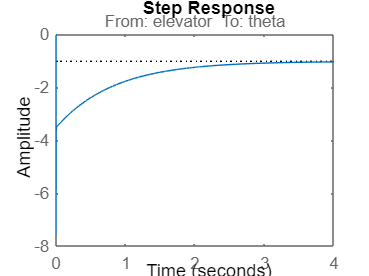

%Pitch
step(Gel_pit)

stepinfo(Gel_pit)

ans = struct with fields:
         RiseTime: 0.2192
    TransientTime: 2.4544e+04
     SettlingTime: 3.9865e+04
      SettlingMin: -7.5487
      SettlingMax: -1.0418
        Overshoot: 632.1713
       Undershoot: 0
             Peak: 7.5487
         PeakTime: 3.0609


damp(Gel_pit)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.20e-04                 1.00e+00       1.20e-04         8.31e+03    
 -1.60e-01 + 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -1.60e-01 - 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -6.20e+00                 1.00e+00       6.20e+00         1.61e-01    
 -1.17e+01 + 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    
 -1.17e+01 - 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    


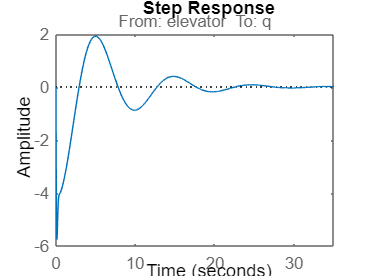

%Pitch Rate
step(Gel_q)

stepinfo(Gel_q)

ans = struct with fields:
         RiseTime: 1.7347e-18
    TransientTime: 21.1506
     SettlingTime: NaN
      SettlingMin: -5.7569
      SettlingMax: 1.9145
        Overshoot: 2.3197e+18
       Undershoot: 7.7143e+17
             Peak: 5.7569
         PeakTime: 0.1179


damp(Gel_q)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.20e-04                 1.00e+00       1.20e-04         8.31e+03    
 -1.60e-01 + 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -1.60e-01 - 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -6.20e+00                 1.00e+00       6.20e+00         1.61e-01    
 -1.17e+01 + 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    
 -1.17e+01 - 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    


**2.1 SAS**

Para diseñar el lazo interno referente al sistema SAS se analiza el lugar de las raices (para ganancias negativas principalemente) de los polos de la función de trasnferencia : 


$$G\left(s\right)=\frac{\dot{\theta} }{\mathrm{Elevator}}$$


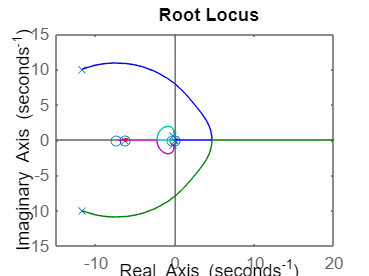

rlocus(Gel_q)

Para ganancias positivas, se puede observar que para valores de K mayores a 0.175 se presenta inestabilidad debido al polo complejo conjugado $-11\ldotp 7\pm 10i$.

En el intervalo $\left\lbrack 0;0\ldotp 175\right\rbrack$, el sistema es estable sin embargo el amortiguamiento del sistema disminuye.

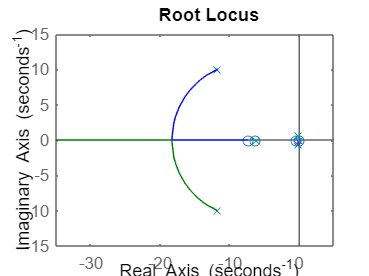

rlocus(-Gel_q)

Para ganacias negativas se evidencia estabilidad para cualquier valor de K, por lo que se selecciona el valor de esta constante como la ganacia necesaria para que el polo menos amortiguado tenga un amortiguamiento equivalente a 1.

Se toma un valor de : 


$$k=-2\ldotp 92$$


kel_q=-2.92;
nd=[1 0];dd=[1];dev=tf(nd,dd)

dev =
 
  s
 
Continuous-time transfer function.



%PropFeedback in PitchRate/Elevator TF 
Gel_qSAS=feedback(Gel_q,kel_q)

Gel_qSAS =
 
  From input "elevator" to output "q":
    -134.1 s^5 - 1869 s^4 - 6807 s^3 - 2268 s^2 - 0.07966 s - 1.917e-17
  ------------------------------------------------------------------------
  s^6 + 421.4 s^5 + 5851 s^4 + 2.149e04 s^3 + 7260 s^2 + 642.2 s + 0.07726
 
Continuous-time transfer function.



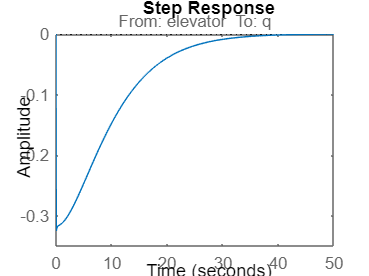

step(Gel_qSAS)

stepinfo(Gel_qSAS)

ans = struct with fields:
         RiseTime: 4.1633e-17
    TransientTime: 31.9013
     SettlingTime: NaN
      SettlingMin: -0.3251
      SettlingMax: 8.0634e-05
        Overshoot: 1.3099e+17
       Undershoot: 3.2491e+13
             Peak: 0.3251
         PeakTime: 0.0541


damp(Gel_qSAS)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.20e-04     1.00e+00       1.20e-04         8.30e+03    
 -1.70e-01     1.00e+00       1.70e-01         5.88e+00    
 -1.94e-01     1.00e+00       1.94e-01         5.15e+00    
 -6.23e+00     1.00e+00       6.23e+00         1.60e-01    
 -7.64e+00     1.00e+00       7.64e+00         1.31e-01    
 -4.07e+02     1.00e+00       4.07e+02         2.46e-03    


%DevFeedback in Pitch/Elevator TF
Gel_pitSAS=feedback(Gel_pit,kel_q*dev)

Gel_pitSAS =
 
  From input "elevator" to output "theta":
            -134.1 s^4 - 1869 s^3 - 6807 s^2 - 2268 s - 0.07966
  ------------------------------------------------------------------------
  s^6 + 421.4 s^5 + 5851 s^4 + 2.149e04 s^3 + 7260 s^2 + 642.2 s + 0.07726
 
Continuous-time transfer function.



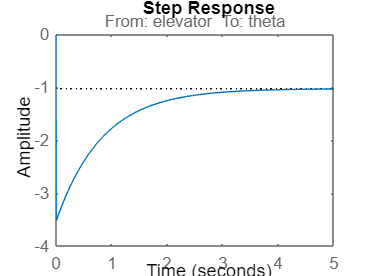

step(Gel_pitSAS)

stepinfo(Gel_pitSAS)

ans = struct with fields:
         RiseTime: 2.7053
    TransientTime: 3.2531e+04
     SettlingTime: 3.9850e+04
      SettlingMin: -3.5210
      SettlingMax: -0.9353
        Overshoot: 241.5094
       Undershoot: 0
             Peak: 3.5210
         PeakTime: 51.9888


damp(Gel_pitSAS)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.20e-04     1.00e+00       1.20e-04         8.30e+03    
 -1.70e-01     1.00e+00       1.70e-01         5.88e+00    
 -1.94e-01     1.00e+00       1.94e-01         5.15e+00    
 -6.23e+00     1.00e+00       6.23e+00         1.60e-01    
 -7.64e+00     1.00e+00       7.64e+00         1.31e-01    
 -4.07e+02     1.00e+00       4.07e+02         2.46e-03    


**2.2 CAS**

Para el diseño del sistema CAS se propone un controlador PI, por ende se analiza el lugar de las raices para el lazo de control externo 

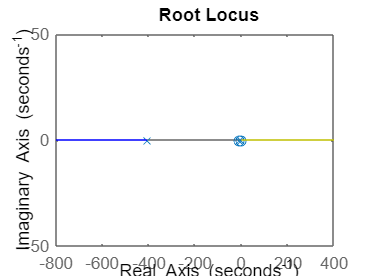

rlocus(Gel_pitSAS)

 A partir del grafico y por medio de iteraciones se llegan a los siguientes valores del controlador 

kiel_pit=-0.025;
kpel_pit=-0.125;
ncpit=[kpel_pit kiel_pit];dcpit=[1 0];
Cpit=tf(ncpit,dcpit)

Cpit =
 
  -0.125 s - 0.025
  ----------------
         s
 
Continuous-time transfer function.



Gel_pitCAS=feedback(Gel_pitSAS*Cpit,1)

Gel_pitCAS =
 
  From input to output "theta":
            16.76 s^5 + 237 s^4 + 897.6 s^3 + 453.7 s^2 + 56.71 s + 0.001991
  ------------------------------------------------------------------------------------
  s^7 + 421.4 s^6 + 5868 s^5 + 2.172e04 s^4 + 8158 s^3 + 1096 s^2 + 56.79 s + 0.001991
 
Continuous-time transfer function.



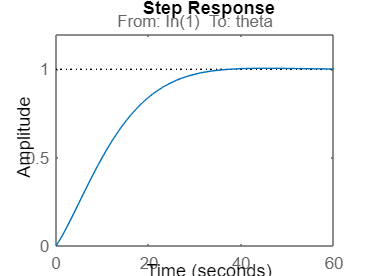

step(Gel_pitCAS)

stepinfo(Gel_pitCAS)

ans = struct with fields:
         RiseTime: 20.9166
    TransientTime: 31.2659
     SettlingTime: 31.2659
      SettlingMin: 0.9009
      SettlingMax: 1.0059
        Overshoot: 0.5908
       Undershoot: 0
             Peak: 1.0059
         PeakTime: 45.4601


**3.Eje Lateral / Direccional - Control PI+D**

%Nomenclatura Variables Eje Lateral/Direccional
%inputs: (8)Aileron ; (3) Ruddle
%Outputs: (5) phi-roll ; (8) roll rate-p ; (7)psi-ywa ; (10) yaw rater-r
latmodtf=tf(latmod)

latmodtf =
 
  From input "aileron" to output...
                 -19.49 s^2 - 214.7 s - 225.8
   beta:  -------------------------------------------
          s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
          -156.9 s^3 - 535 s^2 - 4302 s + 123.9
   p:  -------------------------------------------
       s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
         11.54 s^3 + 115.4 s^2 - 113.6 s - 2302
   r:  -------------------------------------------
       s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
                 -156.3 s^2 - 528.8 s - 4308
   phi:  -------------------------------------------
         s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
             11.55 s^3 + 115.6 s^2 - 113.7 s - 2305
   psi:  -----------------------------------------------
         s^5 + 19.8 s^4 + 90.9 s^3 + 505.1 s^2 + 6.979 s
 
  From input "rudder" to output...
            0.3128 s^3 + 87.06 s^2 + 1309 s - 209.3
   beta:  -------------------------------------------
          s^4 + 19.8 s^3 + 90

**3.1 Aileron - Roll**

Gail_rol=latmodtf(4,1)

Gail_rol =
 
  From input "aileron" to output "phi":
          -156.3 s^2 - 528.8 s - 4308
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



Gail_p=latmodtf(2,1)

Gail_p =
 
  From input "aileron" to output "p":
     -156.9 s^3 - 535 s^2 - 4302 s + 123.9
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



Se obtiene la respuesta al impulso para cada  uno de las funciones de trasnferencia entre el Aileron y la posición y velocidad del ángulo Roll.

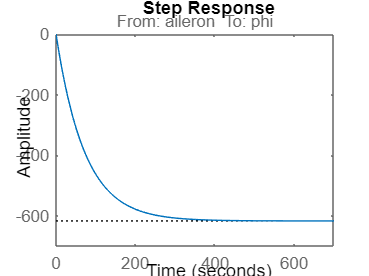

%Roll 
step(Gail_rol)

stepinfo(Gail_rol)

ans = struct with fields:
         RiseTime: 158.6096
    TransientTime: 282.4810
     SettlingTime: 282.4810
      SettlingMin: -617.2824
      SettlingMax: -558.3003
        Overshoot: 0
       Undershoot: 0
             Peak: 617.2824
         PeakTime: 761.3375


damp(Gail_rol)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.39e-02                 1.00e+00       1.39e-02         7.22e+01    
 -1.84e+00 + 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.84e+00 - 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.61e+01                 1.00e+00       1.61e+01         6.21e-02    


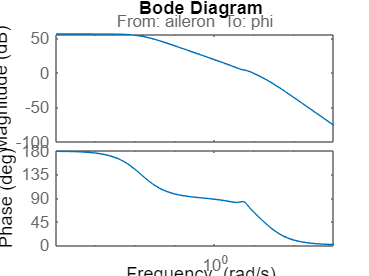

bode(Gail_rol)

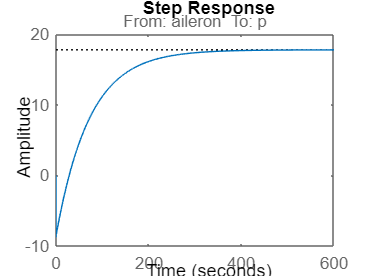

%Roll rate (p)
step(Gail_p)

stepinfo(Gail_p)

ans = struct with fields:
         RiseTime: 158.6246
    TransientTime: 281.9180
     SettlingTime: 310.9016
      SettlingMin: 15.9837
      SettlingMax: 17.7535
        Overshoot: 0
       Undershoot: 49.4024
             Peak: 17.7535
         PeakTime: 605.2001


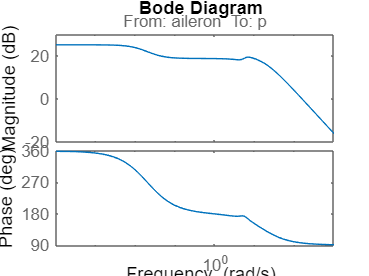

bode(Gail_p)

ail_p=ss(Gail_p)

ail_p =
 
  A = 
            x1       x2       x3       x4
   x1    -19.8   -11.36   -7.892  -0.4362
   x2        8        0        0        0
   x3        0        8        0        0
   x4        0        0     0.25        0
 
  B = 
       aileron
   x1       16
   x2        0
   x3        0
   x4        0
 
  C = 
          x1      x2      x3      x4
   p  -9.807   -4.18  -4.201  0.4841
 
  D = 
      aileron
   p        0
 
Continuous-time state-space model.



**3.1.1 SAS**

Para el diseño del sistema de aumento de estabilidad se analiza los polos de la función de transferencia de la velocidad respecto al aleron en lazo abierto.

damp(Gail_p)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.39e-02                 1.00e+00       1.39e-02         7.22e+01    
 -1.84e+00 + 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.84e+00 - 5.28e+00i     3.29e-01       5.59e+00         5.43e-01    
 -1.61e+01                 1.00e+00       1.61e+01         6.21e-02    


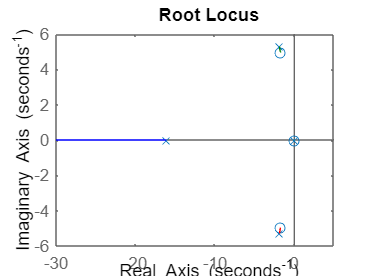

rlocus(-Gail_p)

Se pueded observar que la variación del amortiguamiento depende de la pareja de polos complejos conjugados ubicados 


$$p_{1,2} =-1\ldotp 84\pm 5\ldotp 28\;i$$


El valor absoluto de la constante de realimentación para el sistema SAS varia desde 0 hasta infinito inicialmente. De acuerdo al diagrama del lugar de las raices, el rango de las ganacias negativas para aumentar el amortiguamiento lo maximo posible son :


$$k=\left(-0\ldotp 0627\;,-0\ldotp 111\right)$$


Sin embargo, la presencia de un polo cercano a cero limita el valor de esta ganancia de realimentación. De acuerdo al mismo grafico, el valor minimo de la ganacia para la cual el polo se conserva en el lado izquierdo del plano-s (siendo estable ) es :


$$k=-0\ldotp 0561$$


Por ende este sera el valor que se usará para realizar la realimentación en el sistema SAS

kail_p=0.1;
Gail_pSAS=feedback(Gail_p,kail_p)

Gail_pSAS =
 
  From input "aileron" to output "p":
     -156.9 s^3 - 535 s^2 - 4302 s + 123.9
  --------------------------------------------
  s^4 + 4.105 s^3 + 37.4 s^2 + 74.89 s + 19.37
 
Continuous-time transfer function.



damp(Gail_pSAS)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.03e-01                 1.00e+00       3.03e-01         3.30e+00    
 -1.96e+00                 1.00e+00       1.96e+00         5.11e-01    
 -9.22e-01 + 5.64e+00i     1.61e-01       5.71e+00         1.08e+00    
 -9.22e-01 - 5.64e+00i     1.61e-01       5.71e+00         1.08e+00    


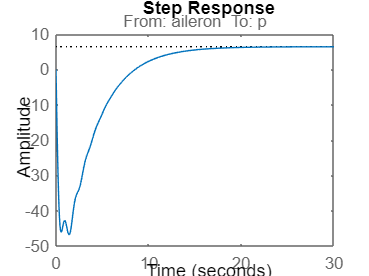

step(Gail_pSAS)

stepinfo(Gail_pSAS)

ans = struct with fields:
         RiseTime: 7.2482
    TransientTime: 14.4753
     SettlingTime: 21.4627
      SettlingMin: 5.7639
      SettlingMax: 6.3936
        Overshoot: 0
       Undershoot: 731.8738
             Peak: 46.8226
         PeakTime: 1.4115


**3.1.2 CAS**

Para el diseño de sistema de aumento de Control se analiza en lazo abierto el sistema SAS haciendo enfasis en la posición (Roll/Aileron).

na=[1 0];da=[1];da=tf(na,da);
Gail_rolSAS=feedback(Gail_rol,da*kail_p)

Gail_rolSAS =
 
  From input "aileron" to output "phi":
           -156.3 s^2 - 528.8 s - 4308
  ---------------------------------------------
  s^4 + 4.167 s^3 + 38.03 s^2 + 74.28 s + 6.979
 
Continuous-time transfer function.



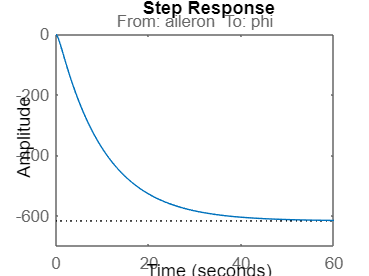

step(Gail_rolSAS)

stepinfo(Gail_rolSAS)

ans = struct with fields:
         RiseTime: 22.2330
    TransientTime: 39.9737
     SettlingTime: 39.9737
      SettlingMin: -616.8734
      SettlingMax: -555.8337
        Overshoot: 0
       Undershoot: 0
             Peak: 616.8734
         PeakTime: 74.0271


damp(Gail_rolSAS)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -9.89e-02                 1.00e+00       9.89e-02         1.01e+01    
 -2.11e+00                 1.00e+00       2.11e+00         4.75e-01    
 -9.81e-01 + 5.70e+00i     1.70e-01       5.79e+00         1.02e+00    
 -9.81e-01 - 5.70e+00i     1.70e-01       5.79e+00         1.02e+00    


**3.2 Rudder - Yaw**

Grud_yaw=latmodtf(5,2)

Grud_yaw =
 
  From input "rudder" to output "psi":
       -82.39 s^3 - 1395 s^2 - 1238 s - 2368
  -----------------------------------------------
  s^5 + 19.8 s^4 + 90.9 s^3 + 505.1 s^2 + 6.979 s
 
Continuous-time transfer function.



Grud_r=latmodtf(3,2)

Grud_r =
 
  From input "rudder" to output "r":
     -82.27 s^3 - 1393 s^2 - 1237 s - 2365
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.

